## **1.Dimensionality reduction of petal data using principal component analysis**

%load iris_dataset
load fisheriris
X = meas'

X =     5.1000    4.9000    4.7000    4.6000    5.0000    5.4000    4.6000    5.0000    4.4000    4.9000    5.4000    4.8000    4.8000    4.3000    5.8000    5.7000    5.4000    5.1000    5.7000    5.1000    5.4000    5.1000    4.6000    5.1000    4.8000    5.0000    5.0000    5.2000    5.2000    4.7000    4.8000    5.4000    5.2000    5.5000    4.9000    5.0000    5.5000    4.9000    4.4000    5.1000    5.0000    4.5000    4.4000    5.0000    5.1000    4.8000    5.1000    4.6000    5.3000    5.0000
    3.5000    3.0000    3.2000    3.1000    3.6000    3.9000    3.4000    3.4000    2.9000    3.1000    3.7000    3.4000    3.0000    3.0000    4.0000    4.4000    3.9000    3.5000    3.8000    3.8000    3.4000    3.7000    3.6000    3.3000    3.4000    3.0000    3.4000    3.5000    3.4000    3.2000    3.1000    3.4000    4.1000    4.2000    3.1000    3.2000    3.5000    3.6000    3.0000    3.4000    3.5000    2.3000    3.2000    3.5000    3.8000    3.0000    3.8000    3.2000    3.7000    3

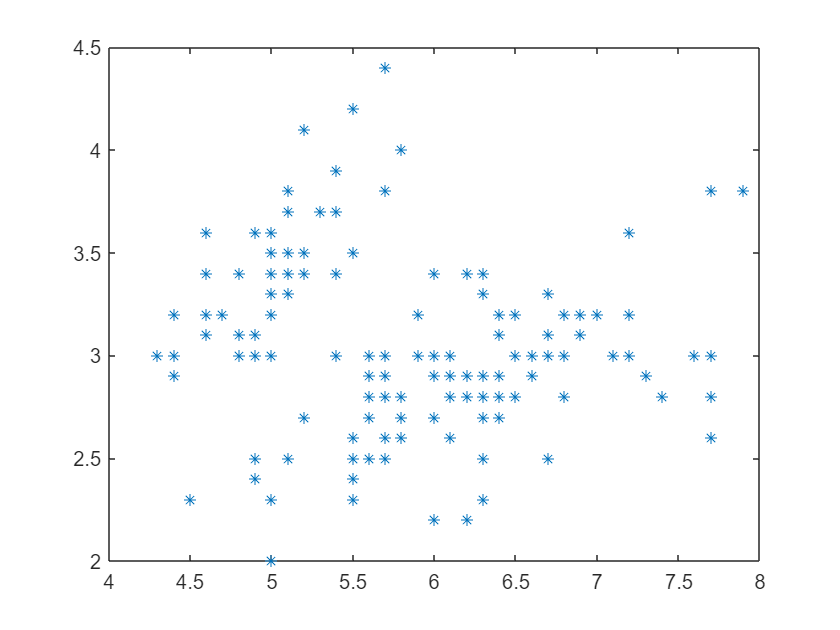

figure;
plot(X(1,:),X(2,:),'*')

%%centering
m = mean(X,2) %求解均值

m =     5.8433
    3.0573
    3.7580
    1.1993


Xcen = X-m*ones(1,150)

Xcen =    -0.7433   -0.9433   -1.1433   -1.2433   -0.8433   -0.4433   -1.2433   -0.8433   -1.4433   -0.9433   -0.4433   -1.0433   -1.0433   -1.5433   -0.0433   -0.1433   -0.4433   -0.7433   -0.1433   -0.7433   -0.4433   -0.7433   -1.2433   -0.7433   -1.0433   -0.8433   -0.8433   -0.6433   -0.6433   -1.1433   -1.0433   -0.4433   -0.6433   -0.3433   -0.9433   -0.8433   -0.3433   -0.9433   -1.4433   -0.7433   -0.8433   -1.3433   -1.4433   -0.8433   -0.7433   -1.0433   -0.7433   -1.2433   -0.5433   -0.8433
    0.4427   -0.0573    0.1427    0.0427    0.5427    0.8427    0.3427    0.3427   -0.1573    0.0427    0.6427    0.3427   -0.0573   -0.0573    0.9427    1.3427    0.8427    0.4427    0.7427    0.7427    0.3427    0.6427    0.5427    0.2427    0.3427   -0.0573    0.3427    0.4427    0.3427    0.1427    0.0427    0.3427    1.0427    1.1427    0.0427    0.1427    0.4427    0.5427   -0.0573    0.3427    0.4427   -0.7573    0.1427    0.4427    0.7427   -0.0573    0.7427    0.1427    0.6427  

%%c=1/n*X*X'
c = 1/150*Xcen*Xcen'  %求解矩阵数据的均方差

c =     0.6811   -0.0422    1.2658    0.5128
   -0.0422    0.1887   -0.3275   -0.1208
    1.2658   -0.3275    3.0955    1.2870
    0.5128   -0.1208    1.2870    0.5771



%%eigendecomposition
[V,D] = eig(c);        %此 MATLAB 函数 返回一个列向量，其中包含方阵 c 的特征值,其中V是特征向量
%%sort(排序)
[inx] = sort(diag(D),'descend')  %此 MATLAB 函数 按降序对对角矩阵D的元素进行排列，并索引对角数值（ascend升序）

inx =     4.2001
    0.2411
    0.0777
    0.0237


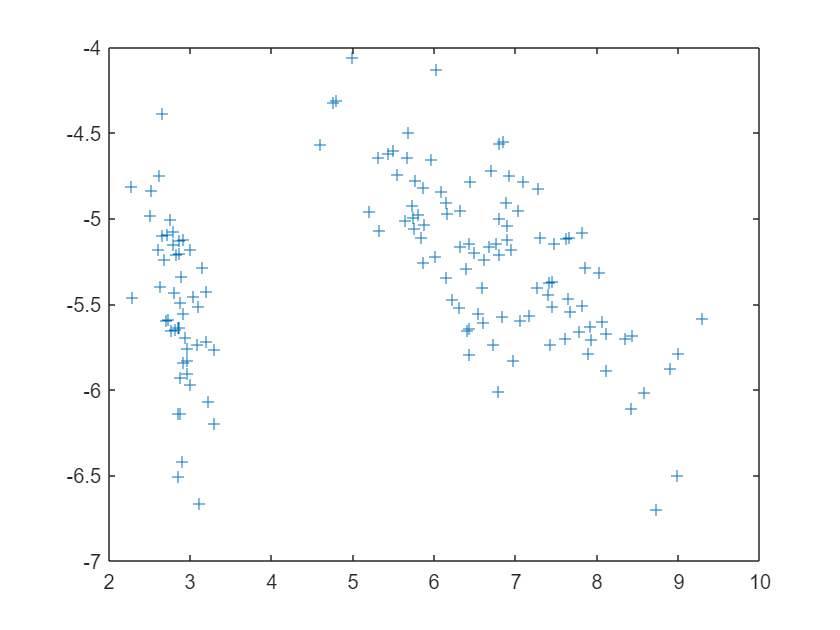

%%Wpca
Wpca = V(:,1:2);          %取v的前两列（特征值最大即主成分）
Xdim = Wpca'*X;           %对原数据X降维，保留主要数据
figure;
plot(Xdim(1,:),Xdim(2,:),'+');